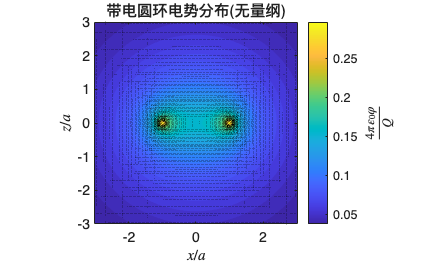

clc; clear; close all;

%定义物理参数
eps0 = 8.854e-12;       
q = 1;                  
Q = 4*pi*eps0*q;       

x = linspace(-3, 3, 150);
z = linspace(-3, 3, 150);
[X, Z] = meshgrid(x, z);
Y = 0;


phi_tilde = zeros(size(X));
theta = linspace(0, 2*pi, 800);
for i = 1:length(theta)
    xp = cos(theta(i));
    yp = sin(theta(i));
    R = sqrt((X - xp).^2 + (Y - yp).^2 + Z.^2);
    phi_tilde = phi_tilde + 1 ./ R;
end
phi_tilde = phi_tilde / length(theta) / (2*pi);  
[Ex, Ez] = gradient(-phi_tilde, x(2)-x(1), z(2)-z(1));

figure;
contourf(X, Z, phi_tilde, 40, 'LineColor', 'none');
cb = colorbar;
cb.Label.Interpreter = 'latex';
cb.Label.String = '$\frac{4\pi \varepsilon_0 \varphi}{Q}$';
title('带电圆环电势分布(无量纲)', 'Interpreter', 'none');
xlabel('$x/a$', 'Interpreter', 'latex');
ylabel('$z/a$', 'Interpreter', 'latex');
axis equal tight;
hold on;
quiver(X, Z, Ex, Ez, 1.5, 'k');
hold off;

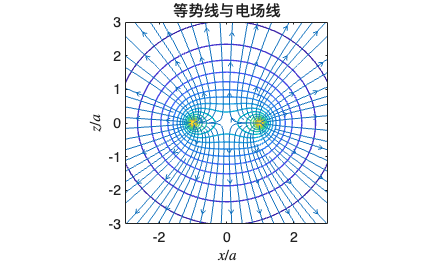


figure;
contour(X, Z, phi_tilde, 20, 'LineWidth', 1);
hold on;
streamslice(X, Z, Ex, Ez);
xlabel('$x/a$', 'Interpreter', 'latex');
ylabel('$z/a$', 'Interpreter', 'latex');
title('等势线与电场线', 'Interpreter', 'none');
axis equal tight;

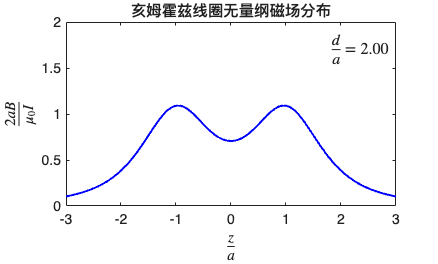

clear; clc;
z_tilde = linspace(-3,3,400);
figure;
for d_tilde = linspace(0.5, 2, 50)
    B_tilde = 1./(1+(z_tilde - d_tilde/2).^2).^(3/2) + ...
              1./(1+(z_tilde + d_tilde/2).^2).^(3/2);

    plot(z_tilde, B_tilde, 'b', 'LineWidth',1.5);
    xlabel('$\displaystyle \frac{z}{a}$','Interpreter','latex');    % 坐标轴用 latex 安全
    ylabel('$\displaystyle \frac{2aB}{\mu_0 I}$','Interpreter','latex');
    title('亥姆霍兹线圈无量纲磁场分布', 'Interpreter', 'none');

    txt = sprintf('$\\displaystyle \\frac{d}{a} = %.2f$', d_tilde);
    htxt = text(0.98, 0.95, txt, 'Units', 'normalized', ...
                'HorizontalAlignment', 'right', 'VerticalAlignment', 'top', ...
                'Interpreter', 'latex', 'FontSize', 12);

    grid off; axis([-3 3 0 2]);
    drawnow; pause(0.08);
end

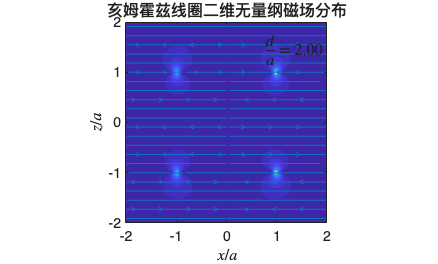

clear; clc;

x = linspace(-2, 2, 60);
z = linspace(-2, 2, 60);
[X, Z] = meshgrid(x, z);

phi = linspace(0, 2*pi, 200);  % 电流元角度采样
dphi = phi(2) - phi(1);

figure;
for d_tilde = linspace(0.5, 2, 40)
    Bx = zeros(size(X));
    Bz = zeros(size(X));

    for signz = [-1, 1]   
        for i = 1:length(phi)
            % 电流元位置
            xp = cos(phi(i));
            yp = sin(phi(i));
            zp = signz * d_tilde / 2;

            % 电流元方向
            dx = -sin(phi(i));
            dy =  cos(phi(i));
            dz =  0;

            % 观测点到电流元的矢量
            Rx = X - xp;
            Ry = -yp;      
            Rz = Z - zp;
            R3 = (Rx.^2 + Ry.^2 + Rz.^2).^(3/2);

            % 比奥–萨伐尔定律
            dBx = (dy.*Rz - dz.*Ry) ./ R3;
            dBz = (dz.*Rx - dx.*Rz) ./ R3;

            Bx = Bx + dBx * dphi;
            Bz = Bz + dBz * dphi;
        end
    end

    % 归一化
    Bmag = sqrt(Bx.^2 + Bz.^2);
    Bmag = Bmag / max(Bmag(:));   % 无量纲化
    Bx = Bx / max(Bmag(:));
    Bz = Bz / max(Bmag(:));

 
    cla;
    contourf(X, Z, Bmag, 30, 'LineColor', 'none');
    hold on;
    streamslice(X, Z, Bx, Bz, 1.2);

    
    axis equal tight;
    xlabel('$x/a$', 'Interpreter', 'latex', 'FontSize', 12);
    ylabel('$z/a$', 'Interpreter', 'latex', 'FontSize', 12);
    title('亥姆霍兹线圈二维无量纲磁场分布', 'Interpreter', 'none', 'FontSize', 12);

    % 在图右上角显示 d/a 数值
    text(0.98, 0.95, sprintf('$\\frac{d}{a}=%.2f$', d_tilde), ...
        'Units','normalized','HorizontalAlignment','right','VerticalAlignment','top', ...
        'Interpreter','latex','FontSize',12);

    hold off;
    drawnow;
    pause(0.1);
end

clear all;close all;clc;

% Trefethen_T.m - 挑战题 T 的数值计算 (纯数值方法)

f = @(x) (1./x) .* cos((1./x) .* log(x));

%使用 fzero

function xk_val = calculate_xk_fzero_improved(k_val, x_prev)
    % x_k 满足 log(x)/x = lambda_k
    lambda_k = -(k_val - 0.5) * pi;
    
    % 定义需要求根的函数
    g = @(x) (log(x)./x) - lambda_k;
    
    % TolX 设置为 1e-20，要求更高的 xk 求解精度
    options = optimset('Display', 'off', 'TolX', 1e-20); 
    
    %优化搜索区间
    %x_upper：前一个根 x_{k-1}
    x_upper = x_prev;
    
    x_lower = 1e-10; 
    if x_upper < x_lower * 10
        x_lower = x_upper / 10;
    end
    x_lower = max(eps, x_lower); 
    
    % 使用区间搜索 [x_lower, x_upper]
    try
        xk_val = fzero(g, [x_lower, x_upper], options); 

    catch ME
        warning('fzero 区间搜索失败，尝试使用 x_upper/2 作为初始点。错误: %s', ME.message);
        xk_val = fzero(g, x_upper / 2, options); 
    end

    %精度检查
    g_val = abs(g(xk_val));
    if g_val > 1e-16 
         warning('k=%d: fzero 求解精度可能不足。根的误差 g(x) = %.2e', k_val, g_val);
    end
end


%计算级数项 T_k 和部分和 S_N

N = 20; 
T_k_values = zeros(N, 1);
x_prev = 1.0; 

fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


fprintf('开始计算级数项 T_k (N=%d 项)...\n', N);

开始计算级数项 T_k (N=20 项)...


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



for k = 1:N
    
    % 计算 x_k
    x_k = calculate_xk_fzero_improved(k, x_prev);
    
    % 数值积分 T_k
    % 设置 AbsTol 和 RelTol 来提高积分精度
    T_k_values(k) = integral(f, x_k, x_prev, 'AbsTol', 1e-18, 'RelTol', 1e-15);
    
    fprintf('k=%2d, x_k = %.15f, T_k = % .15f\n', k, x_k, T_k_values(k));
    
    % 更新 x_{k-1} 为当前的 x_k
    x_prev = x_k;
end

k= 1, x_k = 0.474540999512651, T_k =  0.549449923651782


k= 2, x_k = 0.274410631902848, T_k = -0.340072436812882


k= 3, x_k = 0.203014947543734, T_k =  0.190555879387674
k= 4, x_k = 0.164270051232518, T_k = -0.134393812297379


k= 5, x_k = 0.139385299198095, T_k =  0.104387658834086
k= 6, x_k = 0.121832250855035, T_k = -0.085585513997282


k= 7, x_k = 0.108682147490495, T_k =  0.072652387321859
k= 8, x_k = 0.098406496714609, T_k = -0.063190243766935
k= 9, x_k = 0.090122390466059, T_k =  0.055956297607488
k=10, x_k = 0.083281061121991, T_k = -0.050240298346206
k=11, x_k = 0.077521929873985, T_k =  0.045606136786989
k=12, x_k = 0.072597488123188, T_k = -0.041770867665717
k=13, x_k = 0.068331735380140, T_k =  0.038542717921410


k=14, x_k = 0.064595818325293, T_k = -0.035787004181776
k=15, x_k = 0.061293062658519, T_k =  0.033406303841884
k=16, x_k = 0.058349407354500, T_k = -0.031328369078196
k=17, x_k = 0.055707084319924, T_k =  0.029498467167541
k=18, x_k = 0.053320321142045, T_k = -0.027874362129742
k=19, x_k = 0.051152345819686, T_k =  0.026422931400630


k=20, x_k = 0.049173252989593, T_k = -0.025117827221953




T_SN = sum(T_k_values);

x_Nplus1 = calculate_xk_fzero_improved(N + 1, x_prev);
Error_estimate = abs(integral(f, x_Nplus1, x_prev, 'AbsTol', 1e-18, 'RelTol', 1e-15)); 

fprintf('\n--- 最终结果 (部分和 S_N) ---\n');


--- 最终结果 (部分和 S_N) ---


fprintf('计算项数 N = %d\n', N);

计算项数 N = 20


fprintf('T ≈ S_N = % .15f\n', T_SN);

T ≈ S_N =  0.311117968423274


fprintf('估计误差 |T_{N+1}| ≈ %.2e\n', Error_estimate);

估计误差 |T_{N+1}| ≈ 2.39e-02


fprintf('T 的准确值在 [% .15f, % .15f] 范围内\n', T_SN - Error_estimate, T_SN + Error_estimate);

T 的准确值在 [ 0.287180144111940,  0.335055792734608] 范围内




% 艾特肯$\Delta^2$ 加速法 (问题 3)

fprintf('\n------------------------------------------------------------\n');


------------------------------------------------------------


fprintf('艾特肯 (Aitken) 加速法 (问题 3)\n');

艾特肯 (Aitken) 加速法 (问题 3)


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



S_values = cumsum(T_k_values);

N_Aitken = length(S_values) - 2;
T_bar_values = zeros(N_Aitken, 1);

for k = 1:N_Aitken
    Sk = S_values(k);
    Sk_plus1 = S_values(k + 1);
    Sk_plus2 = S_values(k + 2);
    
    Numerator = (Sk_plus1 - Sk)^2;
    Denominator = Sk_plus2 - 2*Sk_plus1 + Sk;
    
    if abs(Denominator) < 1e-16 
        T_bar_values(k) = NaN;
    else
        T_bar_values(k) = Sk - Numerator / Denominator;
    end
end

% 观察加速后的结果
fprintf('k   |   S_k (原始部分和)   |   T_bar_{k-2} (Aitken 加速)\n');

k   |   S_k (原始部分和)   |   T_bar_{k-2} (Aitken 加速)


fprintf('-------------------------------------------------------\n');

-------------------------------------------------------


for k = 1:N_Aitken
    fprintf('%2d  | % .15f  | % .15f\n', k+2, S_values(k+2), T_bar_values(k));
end

 3  |  0.399933366226574  |  0.331502145990891
 4  |  0.265539553929195  |  0.321122609540550
 5  |  0.369927212763281  |  0.324292250949757
 6  |  0.284341698765999  |  0.322899143993705
 7  |  0.356994086087858  |  0.323636910976443
 8  |  0.293803842320923  |  0.323198200154839
 9  |  0.349760139928411  |  0.323480675952213
10  |  0.299519841582205  |  0.323287906417507
11  |  0.345125978369194  |  0.323425435101798
12  |  0.303355110703477  |  0.323323812955009
13  |  0.341897828624887  |  0.323401068781463
14  |  0.306110824443112  |  0.323340939558146
15  |  0.339517128284996  |  0.323388673550693
16  |  0.308188759206799  |  0.323350135094361
17  |  0.337687226374340  |  0.323381705670960
18  |  0.309812864244597  |  0.323355512805888
19  |  0.336235795645227  |  0.323377488013156
20  |  0.311117968423274  |  0.323358867882512



% 最终加速估计值
T_Aitken = T_bar_values(end);

% Aitken 加速后的误差估计
if N_Aitken >= 2
    Aitken_Error_estimate = abs(T_bar_values(end) - T_bar_values(end-1));
    fprintf('\n最终 Aitken 加速估计 T ≈ % .15f\n', T_Aitken);
    fprintf('Aitken 加速后估计误差 ≈ %.2e\n', Aitken_Error_estimate);
else
    fprintf('\n项数不足，无法计算 Aitken 加速后的误差估计。\n');
end


最终 Aitken 加速估计 T ≈  0.323358867882512


Aitken 加速后估计误差 ≈ 1.86e-05
